# Zonal Wavefront Reconstruction

Sections below are only guaranteed to run correctly when they aresuccessively executed

Changing control values does not automatically run code

clearvars

Define WFS hardware parameters and analysis pupil size

pitchLenslet = 64e-6;  % sampling rate (subaperture size) in m     
pitchPixel = 6.4e-6;                % physical pixel size in m
if pitchLenslet == 256e-6
    datFilename = "Centroid_z7_1um_256um_6.4mm.1.dat";
    focal = 5.9041e-3;                      % lenslet focal length in m 
else
    datFilename = "Centroid_z7_1um_64um_6.4mm.1.dat";
    focal = 1.4761e-3;
end
sd = 3.2e-3;           % pupil semidiameter in m

Load data file as reference grid positions and raw wavefront differences. Wavefront differences are in pixels and are proportional to wavefront slopes. Center reference grid positions about origin my subtracting out the mean and plot it together with intended analysis pupil size to visualize the sampling geometry 

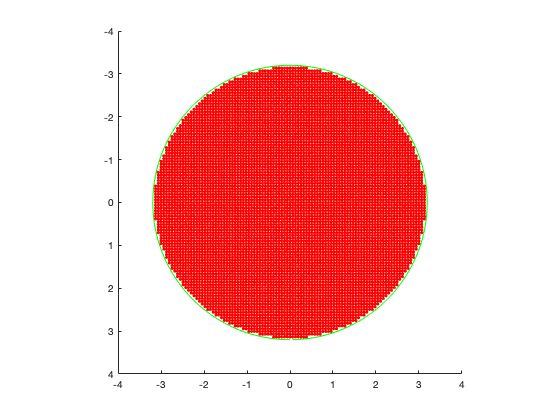

[x, y, dx, dy] = loadWavefrontDifferences(datFilename);
x = (x - mean(x)) * pitchPixel;
y = (y - mean(y)) * pitchPixel;
scatter(x * 1e3, y * 1e3, '.r'), axis square ij
hold on
plot(sd * 1e3 * sind(1:360), sd * 1e3 * cosd(1:360), 'g')
hold off

## Input Data Verification

Represent pupil transmission function with a square matrix where inside the pupil are 1s and all other entries are zeros. This is done by observing unique x values of reference grid

u = unique(x);
N = length(u);
A = false(N); % pupil transmission function
for idx = 1:N
    len = length(find(x == u(idx)));
    a = round(0.5 * (N - len)) + 1;
    b = a + len - 1;
    A(a:b,idx) = true;
end

Evaluate analytical expression for derivative of coma at reference grid sampling locations


$$\frac{\partial Z_{7}}{\partial x} =  c_{7} 6\sqrt8 x y$$



$$\frac{\partial Z_{7}}{\partial y} =  c_{7} \sqrt8 (3 x^2 + 9 y^2 - 2)$$


zx = 6 * sqrt(8) * (x/sd) .* (y/sd);
zy = sqrt(8) * (3 * (x/sd).^2 + 9 * (y/sd).^2 - 2);

Set up wavefront slopes and execute iterative FFT algorithm

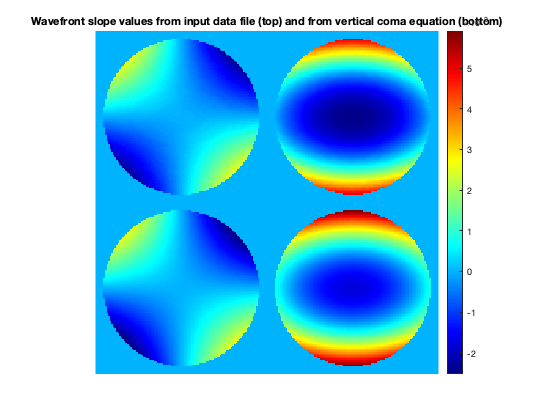

% Construct analytical and measured slope meshgrids
Mx = zeros(N);
My = zeros(N);
Ax = zeros(N);
Ay = zeros(N);
k = 1;
for idx = 1:numel(A)
    if A(idx)
        Ax(idx) = zx(k) / (sd * 1e6);
        Ay(idx) = zy(k) / (sd * 1e6);
        Mx(idx) = pitchPixel * dx(k) / focal;
        My(idx) = pitchPixel * dy(k) / focal;
        k = k + 1;
    end
end

% Pad and compare the results
pad_dim = [5 5];
Mx = padarray(Mx', pad_dim);
My = padarray(My', pad_dim);
Ax = padarray(Ax', pad_dim);
Ay = padarray(Ay', pad_dim);
A = padarray(A, pad_dim);
imagesc([Mx My; Ax Ay]), axis image off
title("Wavefront slope values from input data file (top) and from vertical coma equation (bottom)")
colorbar

Reconstruct wavefront from slope data

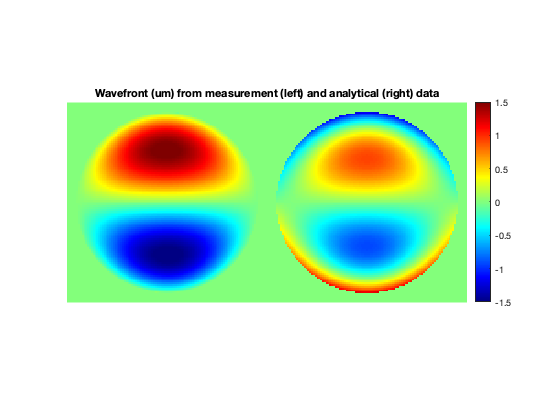

iterations = 20;
[Wa, ~] = zonalIterativeFourier(Ax, Ay, A, pitchLenslet, iterations);
[Wm, ~] = zonalIterativeFourier(Mx, My, A, pitchLenslet, iterations);

% draw wavefront
imagesc([(Wm * 1e6) (Wa * 1e6)]), axis image off
caxis([-1.5 1.5])
title('Wavefront (um) from measurement (left) and analytical (right) data')
colormap('jet')
colorbar
axis image off

Verify wavefront rms

w = 1e6 * Wa(A); % wavefront values in microns
rms = sqrt(w' * w / length(w))

rms =           0.49
